clc
clear all

% Get RIR from the sine sweep measurements
% Deconvolution

%TODO%
%[sine_sweep,fs] = audioread('sineSweep.wav');

number_of_discrete_positions = 12;
number_of_speakers = 2;

number_of_mics = ['A','B','C','D','E','F'];

speakers_all_discrete_positions = cell(number_of_discrete_positions,number_of_speakers);

for i=1:number_of_discrete_positions
    for j=1:length(number_of_mics)
        %disp(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(3+i) '.wav'])
        %disp('-----')
        if i+3 >= 10
            [audioData, fs] = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(3+i) '.wav']);
        else
            [audioData, fs] = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_00' num2str(3+i) '.wav']);
        end
        truncatedAudioData = audioData(1:630000);

        % TODO:
        %rir = deconvolve(recordedSignal, sineSweep);

        speakers_all_discrete_positions{i,1}(:,j) = truncatedAudioData;
    end
end

for i=1:number_of_discrete_positions
    for j=1:length(number_of_mics)
        %disp(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(15+i) '.wav'])
        %disp('-----')
        audioData = audioread(['Measurements_Team4\Recordings SPAI\mic' num2str(number_of_mics(j)) '_0' num2str(15+i) '.wav']);
        truncatedAudioData = audioData(1:630000);

        % TODO:
        %rir = deconvolve(recordedSignal, sineSweep);

        speakers_all_discrete_positions{i,2}(:,j) = truncatedAudioData;
    end
end        

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 48000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



DOA = cell(number_of_discrete_positions,number_of_speakers);
P = cell(number_of_discrete_positions,number_of_speakers);

for i=1:number_of_discrete_positions
    DOA{i,1} = SDMbf(speakers_all_discrete_positions{i,1}, a);
end

Started SDM processing
Ended SDM processing in 0.049365 seconds.
Started SDM processing
Ended SDM processing in 0.037706 seconds.
Started SDM processing
Ended SDM processing in 0.03327 seconds.
Started SDM processing
Ended SDM processing in 0.032249 seconds.
Started SDM processing
Ended SDM processing in 0.038124 seconds.
Started SDM processing
Ended SDM processing in 0.03089 seconds.
Started SDM processing
Ended SDM processing in 0.028589 seconds.
Started SDM processing
Ended SDM processing in 0.035462 seconds.
Started SDM processing
Ended SDM processing in 0.029801 seconds.
Started SDM processing
Ended SDM processing in 0.02827 seconds.
Started SDM processing
Ended SDM processing in 0.028382 seconds.
Started SDM processing
Ended SDM processing in 0.02808 seconds.


for i=1:number_of_discrete_positions
    DOA{i,2} = SDMbf(speakers_all_discrete_positions{i,2}, a);
end

Started SDM processing
Ended SDM processing in 0.033584 seconds.
Started SDM processing
Ended SDM processing in 0.032695 seconds.
Started SDM processing
Ended SDM processing in 0.028144 seconds.
Started SDM processing
Ended SDM processing in 0.027904 seconds.
Started SDM processing
Ended SDM processing in 0.028868 seconds.
Started SDM processing
Ended SDM processing in 0.030379 seconds.
Started SDM processing
Ended SDM processing in 0.030308 seconds.
Started SDM processing
Ended SDM processing in 0.031076 seconds.
Started SDM processing
Ended SDM processing in 0.028442 seconds.
Started SDM processing
Ended SDM processing in 0.026948 seconds.
Started SDM processing
Ended SDM processing in 0.027868 seconds.
Started SDM processing
Ended SDM processing in 0.032411 seconds.


% TAKE THE MIDDLE ONE OF THE MICROPHONE ARRAY, THIS IS THE TOP ONE E

for i=1:number_of_discrete_positions
    P{i,1} = speakers_all_discrete_positions{i,1}(:,5);
end

for i=1:number_of_discrete_positions
    P{i,2} = speakers_all_discrete_positions{i,2}(:,5);
end

%save variables in file to use it in another file
save("pressure.mat","P")
save("DOA.mat","DOA")

%save('.\outputDataCalculateSRIR\cell1', 'P')

% Export P, DOA and RIRI to csv file, speaker 1
%for i=1:number_of_discrete_positions
%    csvwrite(['.\outputDataCalculateSRIR\RIR_output_position' num2str(i) '.csv'], speakers_all_discrete_positions{i,1});
%    csvwrite(['.\outputDataCalculateSRIR\DOA_output_position' num2str(i) '.csv'], DOA{i,1});
%    csvwrite(['.\outputDataCalculateSRIR\P_output_position' num2str(i) '.csv'], P{i,1});
%end

% Export P, DOA and RIRI to csv file, speaker 2
% for i=1:number_of_discrete_positions
%     csvwrite(['.\outputDataCalculateSRIR\RIR_output_position' num2str(i) '.csv'], speakers_all_discrete_positions{i,2});
%     csvwrite(['.\outputDataCalculateSRIR\DOA_output_position' num2str(i) '.csv'], DOA{i,2});
%     csvwrite(['.\outputDataCalculateSRIR\P_output_position' num2str(i) '.csv'], P{i,2});
% end

v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','Pori, Concert Hall','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 48000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'Pori, Concert Hall'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



Started visualization of parameters.


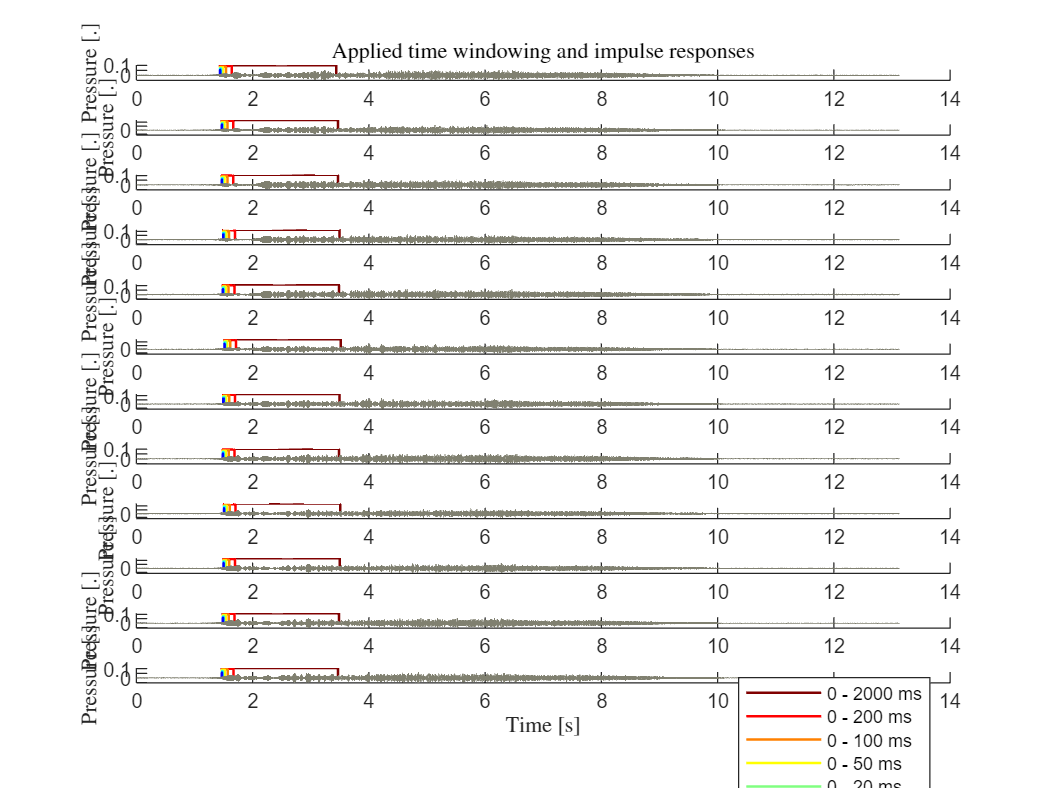

Ended visualization of parameters in 1.137 seconds.


% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
parameterVisualization(P, v);

Started time-frequency visualization.


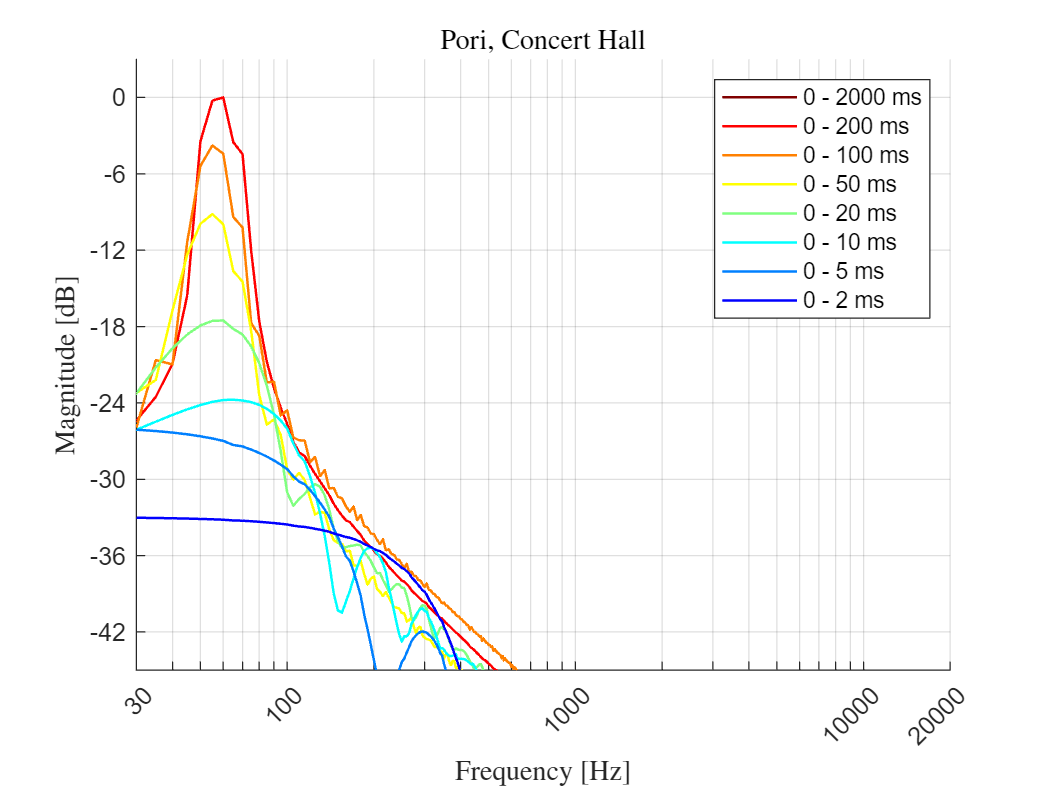

Ended time-frequency visualization in 4.1834 seconds.


timeFrequencyVisualization(P, v)

Started spatio-temporal visualization.


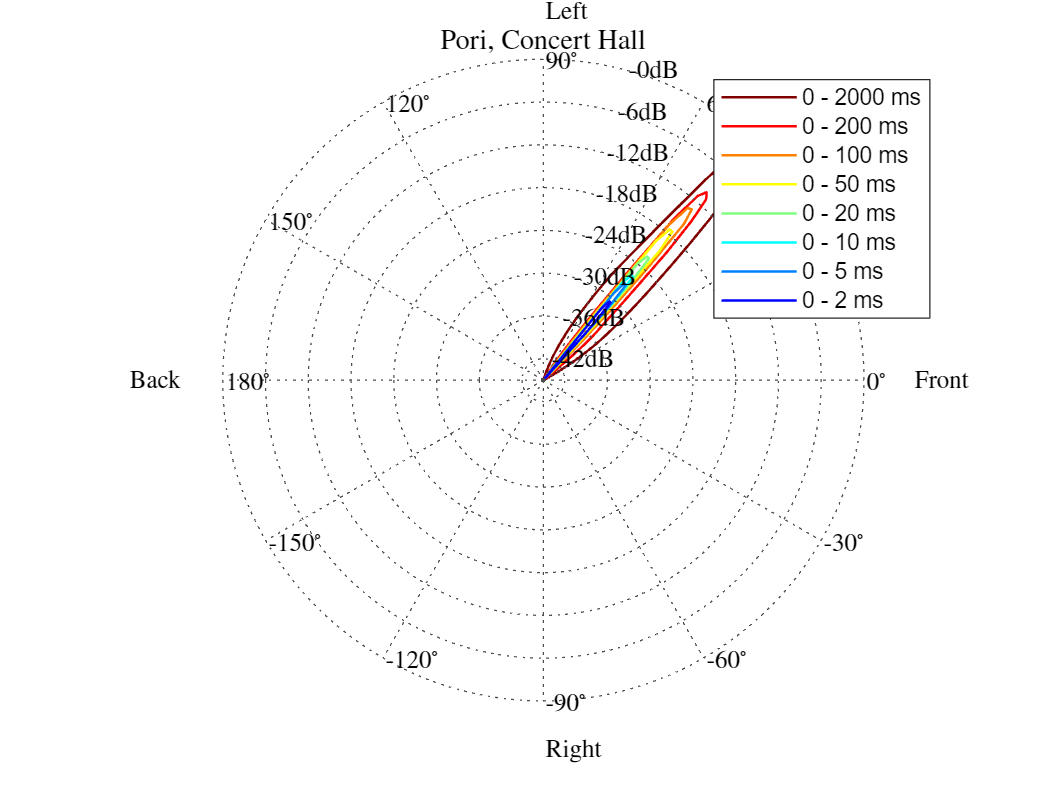

Ended spatio-temporal visualization in 2.1437 seconds.


ans = -50

v.plane = 'lateral';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


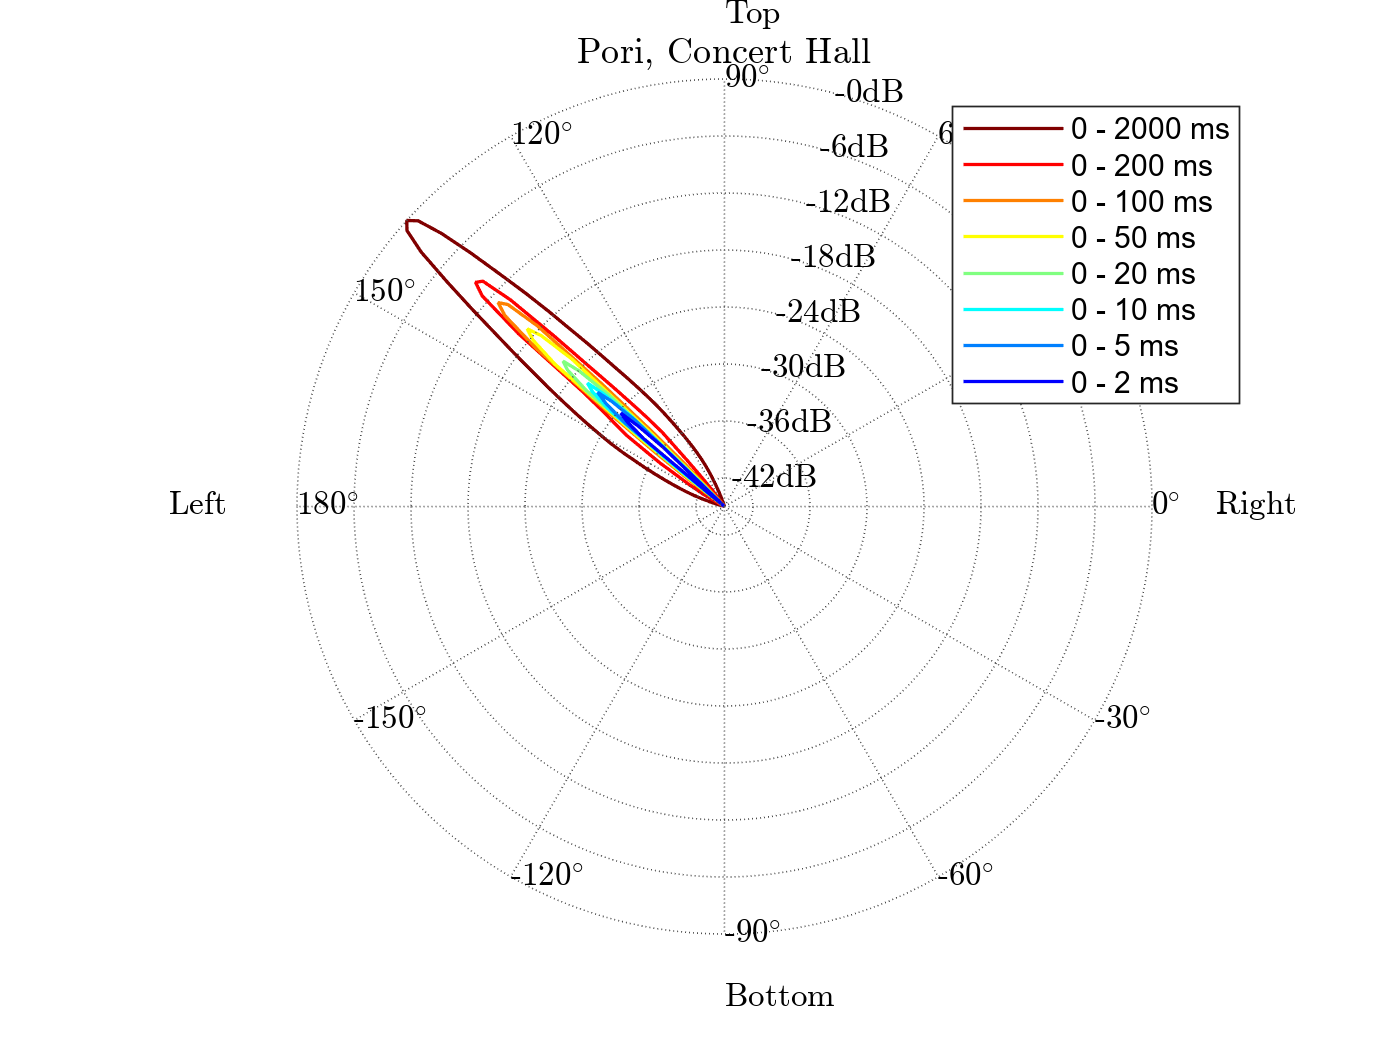

Ended spatio-temporal visualization in 1.7165 seconds.


ans = -139

v.plane = 'transverse';
spatioTemporalVisualization(P, DOA, v)

Started spatio-temporal visualization.


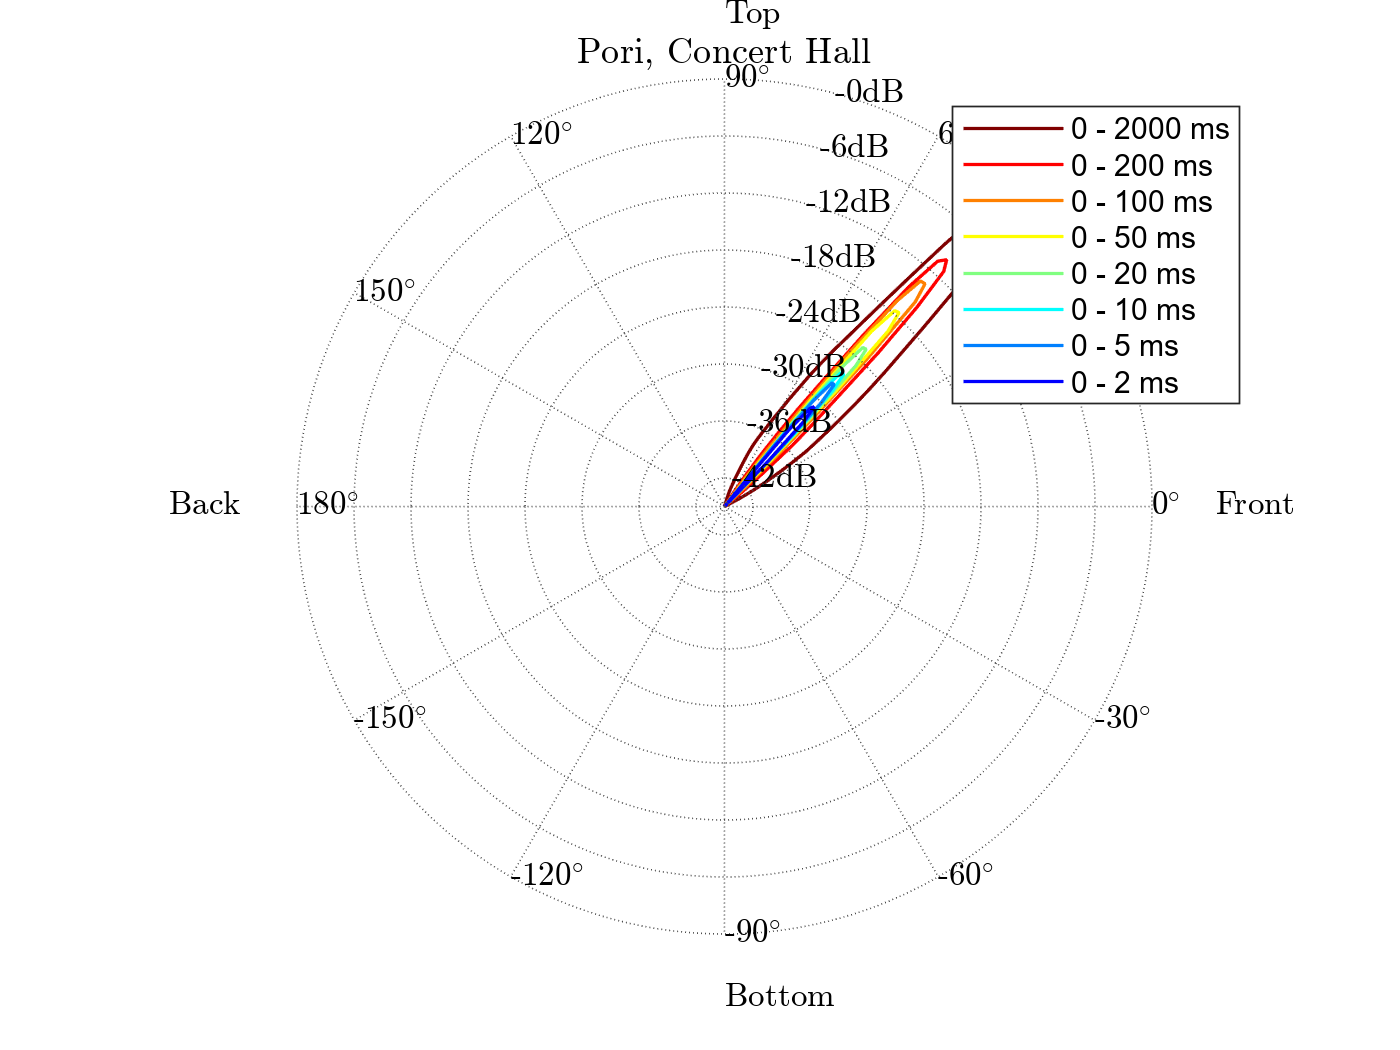

Ended spatio-temporal visualization in 1.6889 seconds.


ans = -49

v.plane = 'median';
spatioTemporalVisualization(P, DOA, v)

% Plot RIR in room
% https://nl.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-image-source-method-and-hrtf-interpolation.html